# Car Control (B) Assignment Live Script

### Setting initial values

% constant speed u (m/s)
u = 0.05;

% desired location [(m) (m)]
p_d = [10, 3.2];

% input ranges
dv_range = [0 1];
dh_range = [0 1];
theta_range = [-180 180];

% output range
dtheta_range = [-130 130];

% initial starting angles
theta_init = [0 -45 -90];

% define maximum position values
x_max = 10;
y_max = 4;

% define max number of iterations
N = 1000;

% starting location
p_init = [4 0.4];

% define obstacle points
p_obs = [5 0; 5 1; 6 1; 6 2; 7 2; 7 3; 10 3];

#### Import FIS

car_fis = readfis('car_control');

#### Plot

if not(isfolder('plots'))
    mkdir 'plots'
end
if not(isfolder('res'))
    mkdir 'res'
end

Plot normalized horizontal distance (Input)

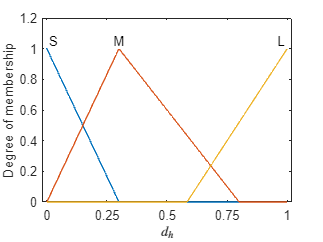

figure;
hold on; box on;
plotmf(car_fis, 'input', 1);
axis([-0.02 1.02 0 1.2]);
xticks(linspace(dh_range(1),dh_range(2),5));
xlabel('$d_h$', 'Interpreter', 'Latex');
saveas(gcf, 'plots/membership_dh.png');

Plot normalized vertical distance (Input)

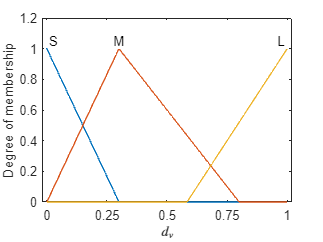

figure;
hold on; box on;
plotmf(car_fis, 'input', 2);
axis([-0.02 1.02 0 1.2]);
xticks(linspace(dv_range(1),dv_range(2),5));
xlabel('$d_v$', 'Interpreter', 'Latex');
saveas(gcf, 'plots/membership_dv.png');

Plot direction angle (Input)

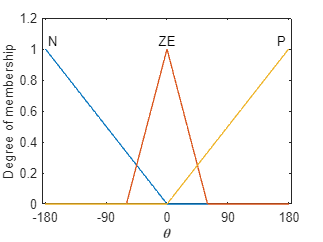

figure;
hold on; box on;
plotmf(car_fis, 'input', 3);
axis([-185 185 0 1.2]);
xticks(linspace(theta_range(1),theta_range(2),5));
xlabel('$\theta$', 'Interpreter', 'Latex');
saveas(gcf, 'plots/membership_theta.png');

Plot direction difference (Output)

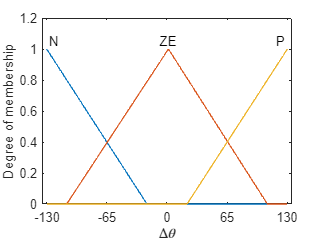

figure;
hold on; box on;
plotmf(car_fis, 'output', 1);
axis([-135 135 0 1.2]);
xticks(linspace(dtheta_range(1),dtheta_range(2),5));
xlabel('$\Delta \theta$', 'Interpreter', 'Latex');
saveas(gcf, 'plots/membership_dtheta.png');

#### Run FIS

Starting angle: 0 degrees

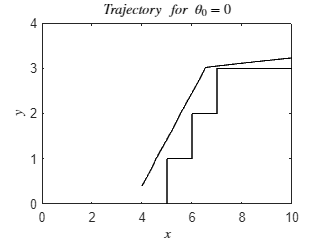

[x, y] = run_fis(p_init, theta_init(1), car_fis);

res = [length(x) x(end) y(end) ((x(end)+x(end-1))/2) ((y(end)+y(end-1))/2)];
res = array2table(res);
res.Properties.VariableNames(1:5) = {'iterations', 'x_final', 'y_final', 'mean_x', 'mean_y'};
writetable(res, 'res/res_th0.csv');

figure;
hold on;box on;
axis([0 10 0 4]);
plot(x, y, 'k');
plot(p_obs(:,1), p_obs(:,2), 'k');
xlabel('$x$', 'Interpreter', 'Latex');
ylabel('$y$', 'Interpreter', 'Latex');
title('$Trajectory\ for\ \theta_0 = 0$', 'Interpreter', 'Latex');

Starting angle: -45 degrees

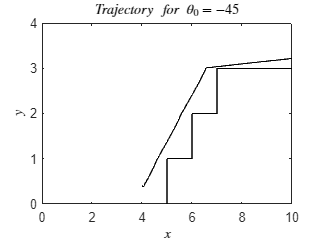

[x, y] = run_fis(p_init, theta_init(2), car_fis);

res = [length(x) x(end) y(end) ((x(end)+x(end-1))/2) ((y(end)+y(end-1))/2)];
res = array2table(res);
res.Properties.VariableNames(1:5) = {'iterations', 'x_final', 'y_final', 'mean_x', 'mean_y'};
writetable(res, 'res/res_th-45.csv');

figure;
hold on;box on;
axis([0 10 0 4]);
plot(x, y, 'k');
plot(p_obs(:,1), p_obs(:,2), 'k');
xlabel('$x$', 'Interpreter', 'Latex');
ylabel('$y$', 'Interpreter', 'Latex');
title('$Trajectory\ for\ \theta_0 = -45$', 'Interpreter', 'Latex');

Starting angle: -90 degrees

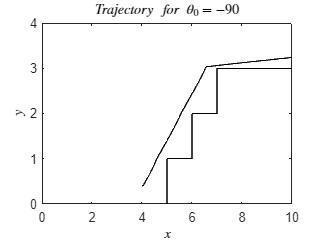

[x, y] = run_fis(p_init, theta_init(3), car_fis);

res = [length(x) x(end) y(end) ((x(end)+x(end-1))/2) ((y(end)+y(end-1))/2)];
res = array2table(res);
res.Properties.VariableNames(1:5) = {'iterations', 'x_final', 'y_final', 'mean_x', 'mean_y'};
writetable(res, 'res/res_th-90.csv');

figure;
hold on;box on;
axis([0 10 0 4]);
plot(x, y, 'k');
plot(p_obs(:,1), p_obs(:,2), 'k');
xlabel('$x$', 'Interpreter', 'Latex');
ylabel('$y$', 'Interpreter', 'Latex');
title('$Trajectory\ for\ \theta_0 = -90$', 'Interpreter', 'Latex');

### Functions

#### Calculate distance from objects

function [dH, dV] = calcDist(x, y)

    if      (y < 1), dH = 5 - x;
    elseif  (y < 2), dH = 6 - x;
    elseif  (y < 3), dH = 7 - x;
    else           , dH = inf;
    end

    if      (x < 5), dV = y;
    elseif  (x < 6), dV = y - 1;
    elseif  (x < 7), dV = y - 2;
    else           , dV = y - 3;
    end
end

#### Check if inside bounds

function res = chkBounds(x, y)

    res = (x < 10 & ...
            x > 0 & ...
            y < 4 & ...
            y > 0);
end

#### Normalize dH, dV

function [dh, dv] = normDist(dH, dV)
    dh = min(1, max(0, dH / 10));
    dv = min(1, max(0, dV / 4));
end

#### Simulate Car Control

function [x, y] = run_fis(p0, theta0, flc)
    
    % max number of iterations
    N = 1000;

    % car speed
    u = 0.05;

    x = zeros(N, 1);
    y = zeros(N, 1);

    i = 1;
    x(i) = p0(1);
    y(i) = p0(2);
    theta = theta0;

    while chkBounds(x(i), y(i)) && i < N
        [dH, dV] = calcDist(x(i), y(i));
        [dh, dv] = normDist(dH, dV);

        dtheta = evalfis(flc, [dh dv theta]);
        
        i = i + 1;

        theta = theta + dtheta;
        if      theta >  180, theta = theta - 360;
        elseif  theta < -180, theta = theta + 360;
        end

        x(i) =  x(i-1) + u*cosd(theta);
        y(i) =  y(i-1) + u*sind(theta);
    end

    x = x(1:i);
    y = y(1:i);
end